## **System modeling**

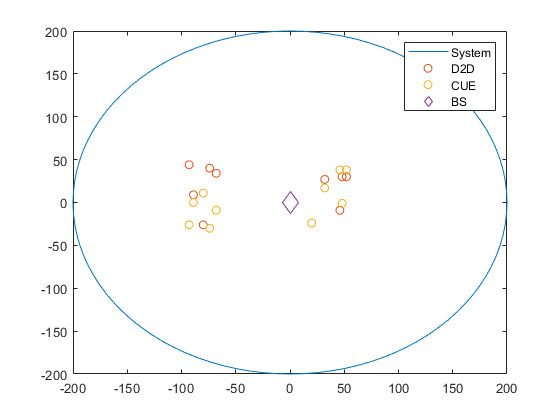

th = 0:pi/50:2*pi;
x=0;
y=0;
r=200;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
number=randi([-100 70],1,10);
D2D=randi([-30 50],1,10);
CUE=randi([-30 50],1,10);
BS=0;
plot(xunit,yunit)
hold on
scatter(number,D2D);
hold on
scatter(number,CUE);
hold on
scatter([0],BS,140,'d');
hold off
legend('System','D2D','CUE','BS');

## **Test for Prematching Algorithm**

% C=[1:30];
% D=[1:30];
% Pkc=0.2;
% pth1=10*10^(-6);
% TminD=2;
% N0=1e-13;
% N1=1e-13;
% Pmax=0.2
% path_loss_exponent=3;
% hD=h_rayleigh1*30^(-path_loss_exponent);
% hki=normrnd(0,1)*50^(-path_loss_exponent);
% lambda_min=(pth1)/(Pmax*hD+Pkc*hki+N0);
% Tmax=log2(1+(Pmax*hD)/(Pkc*hki+N0+(N1)/(1-lambda_min)));
% Num=linspace(10,70,7);
% PFMR=[]
% for i=10:10:70
%    D=[1:i];
%    C=[1:i];
%    [SiD,InfD,EhaD]=Prematch(D,C,Pkc,pth1,Pmax,TminD);
%    SiD
%    b=size(InfD(InfD~=0),2);
%    temp=(b/i)*100;
%    PFMR(end+1)=temp;
% end
% plot(Num,PFMR)

% [SiD,InfD,EhaD]=Prematch(D,C,Pkc,pth1,Pmax,TminD);
% SiD
% a=size(EhaD(EhaD~=0),2)
% b=size(InfD(InfD~=0),2);

## **Test for partner selection**

% M = containers.Map('KeyType','double','ValueType','int32');
% test=rand(1,10);
% for i=1:size(test,2)
%     M(test(i))=i;
% end
% test=sort(test);
% partner=[];
% EE=[];
% EhaD=[1 2 3 4 5 6 7 8];
% SiD=[6 10 2.5 2 1 7 5];
% for i=1:size(EhaD,2)
%     for k=1:size(SiD,2)
%         EE(i,k)=EhaD(i)*SiD(k);
%     end
% end
% for i=1:size(EE,1)
%     EE(i,:)=sort(EE(i,:),'descend');
% end
% for i=1:size(EhaD,2)
%     temp_EE=EE(i,:);
%     for p=1:size(temp_EE,2)
%         a=temp_EE(p)/EhaD(i);
%         link=find(SiD==a);
%         partner(i,p)=link;
%     end
% end


## **Test for Rayleigh channel coefficient generation**

% N= 1000;
% h=(1/sqrt(2))*(randn(N,1)+1i*randn(N,1));

## **Received Power PR**

function P=PR(lambda,PD,h_k,hD,PC)
syms N0 
P=lambda*(PD*hD+PC*h_k+N0);
end

## **Throughput equation for CUE links**

function T=Throughput_C(PD,h_iB,h_kc,P_kc)
syms N0 N1
T=log2(1+(P_kc*h_kc)/(PD*h_iB+N0+N1));
end

## **Throughput equation for D2D links.**

For this function, we take the power splitting ratio lambda, transmission power fo D2D links PD, transmission of CUE, interference hki, and hD

function T=Throughput_D(lambda,PD,P_kc,h_ki,hD)
syms N0 N1
T=log2(1+((1-lambda)*(PD*hD))/((1-lambda)*(P_kc*h_ki+N0)+N1));
end

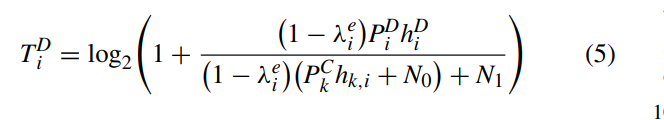

## Piecewise Energy Harvesting model

we take a received power as an input argument for the Energt Harvesting model where the received power is from different segemnts,

then we compare each segment's received power and compare it to the threshold power Pth, then we can get the ouput Harvested power  **E.**

function E=Eenergy_harvesting(PR)
syms k b Pmax Pth L
 if PR>Pth(1) &&  PR<Pth(2)
     E=0;
 % Traverse the Pth array then compare each segment's power
 elseif PR>Pth(2) && PR<Pth(L+1)
     for j=2:L
         if PR>Pth(j) && PR<Pth(j+1)
             E=k(j)*PR+b(j);
             break;
         end
     end
 else
     E=Pmax;
 end
 
end

##  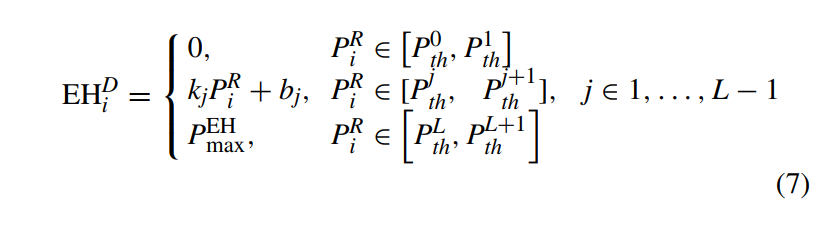

## **Total Energy Consumption EC_iD**

For this function we want to find the total energt consumption EC, so the basic idea will be taking the transmission power PD , circuit power consumption  P_iR and the harvested power EH, and the equatio in the picture below will be used to caculate the energy consumption, the EH can be

obtained from the function **EH**

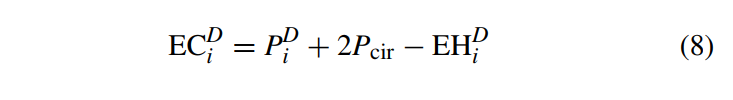

function E=Energy_Consumption(PD,P_ir,EH)
    E=PD+2*P_ir-EH;
end

## **Prematching Algorithm**

This algorithm will be used to match every possible link i of D2D links with CUE link to divide the D2D links into two different groups:

- SWIPT-Eanbled D2D links **EhaD**

- Non EH D2D group which can not perform SWIPT **InfD**

First create three different empty sets for output and they are **EhaD,InfD,SiD. **And we take maximum value of Transmission power of D2D links **Pmax**

**, **minimum value of Throughput of D2D lins **TminD, **transmission power of CUE link K which is always the same in this reference paper, D2D links set noted as **D **, CUE links noted as **C. **Thresholds for received power **P_iR **as the input arguments, then we can start with the prematching algorithm:

- First we need to traverse the D2D links **D **to scan every possible link i

- Then for the **ith** segment of set **D, **we need to figure out if the current segment of CUE match with the segment i of D

- To finish the matching , we need to meet two requiremnts

                1.The power splitting ratio lambda for each segment i is not supposed to exceed 1

                2.The maximum value of Throughput of each  D2D link **i ** is  supposed to be greater than the minimum value D2D links: **T_iD_max>T_min_D**

          4.So for each segment of CUE set **k**, if this segment doesn't meet neither one of the requirements above, then the partner selection set **S_iD **will remove the current k segment, in the code it was noted as **0.**

          5. So for each segment of D2D links **i, **it will match all the segments of the CUE sets to figure out if the current segment matches the current segment of D2D link i

         6. Once finishing scanning every segment **k **of CUE set, it will check if the partner selection set **S_iD **is empty, if so, that means there is no segment in CUE set matcing the current segment i then, the current segemnt i will be added into the Non-EH group **InfD, **if not, it means there is at least one segment **k **in the CUE set which can match the current segment **i **of D2D link, then it will be added into the SWIPT-Enabled group **EhaD. (if at each iteration of segment i of D2D link, if the partner selection set is not all zeros it means it has at least one segment which will match the current segment  i of the whole D2D link)**

        7.Afther the prematching algorithm, we shall get a SWIPT-Enabled D2D link set **EhaD** which has some links that can perform SWIPT and the non-EH D2D group which can not perform SWIPT. The final partner selection set will have the remaining segments which can match the corresponding D2D link, E.g.if the final SiD=[ 1 2 3 4 5 0 0; 1 0 3 4 5 0 7; 1 2 0 4 0 0 7 ...]; That means tha for the first segemnt of D2D links, the CUE set has 5 links which can match the segment **1. ** And for the segment **2 **of D2D links, the CUE sets has 5 links which can match the segment 2, the same for the other segments of D2D links,assuming CUE set has 7 segments in this case(**That is why a CUE segment can appear in more than one partner selection according to the reference paper.**)

function [SiD,InfD,EhaD] = Prematch(D,C,Pkc,Pth1,Pmax,TminD)
% set the channel responses of D2D link and channel responses from D2D link
% and CUE link
syms hD h_interference_D2D_CUE 
syms lambda_min T_max
syms path_loss_exponent
N0=1e-13;
N1=1e-13;
%initialize minimum power splitting ratio, it is supposed to be an array
%response
PC=0.2;
%initialize maximum Throughpu
%Non-EH D2D links
InfD=[];
%SWIPT-Eanbled communication system
EhaD=[];
path_loss_exponent=3;
for i=1:size(D,2)
    SiD(i,:)=C;
    for k=1:size(C,2)
        %\lamda ie
        h1=sqrt(1/2)*normrnd(0,1);
        h2=sqrt(1/2)*normrnd(0,1);
        hD=h1*randi([10 60],1,1)^(-path_loss_exponent);
        hki=randi([50 400],1,1)^(-path_loss_exponent)*h2;
        lambda_min=Pth1/(Pmax*hD+PC*hki+N0);
        scalor=N1/(1-lambda_min);
        T_max=log2(1+(Pmax*hD)/(Pkc*hki+N0+scalor));
        %compare the minimum power splitting ratio and maximum
        %Throughput,if both of the requiremnts can not be met, then the k
        %will be removed from the selection set.
        if lambda_min<0 || lambda_min>1 || T_max<=TminD
            SiD(i,k)=0;
        end 
    end
    %After the CUE set was scanned, then check if the selection set is
    %empty,if so add the segment to the non EH group if not, then add it to
    %the Enabled SWIPT D2D groups.
    temp=SiD(i,:);
    temp=temp(temp~=0);
    if isempty(temp)==0
        InfD(end+1)=0;
        EhaD(end+1)=i;
    else
        EhaD(end+1)=0;
        InfD(end+1)=i;
    end
end
            
        
end

## Outer loop Algorithm

After using inner loop Algorithm, the corresponding output can be used as input argument in the outer loop Algorithm

- First scan each of the SWIPT-Enabled D2D segment

- Then search for all the potential segments that can be matched with segement i in the SWIPT-Enabled set

- Scan all the segment in the piecewise EH model, and for each segment of SWIPT-Enabled D2D communication links, choose the j segment wherer the Energy Efficiency reaches the maximum point which is the optimal **j**

- Use the optimal **j ** to find the optimal value of **transmission power PD**, **power splitting ratio lambda_i **and **Energy efficiency EE**

- Then at the end of the Algorithm, i should get three data arrays: Energy Efficiency, power splitting ratio and Transmission power

So for each D2D link i matching with every possible CUE k, the EE should have j values, then 

function [Pid_optimal,lambda_optimal,EE_optimal]=Outer(EhaD,SiD,lambda,P_ijD,EE_ijD)
%first of all, we need to search the whole SWIPT-Enabled D2D communication
%system, then search for the partner selection set obtained by the
%pre-matching algorithm. Then we set Nmax segments first then search them,
%for each segment, we need to find the maxmimum Energy Efficiency of each
%segment and the j value at which Energy efficiecny reaches its maximum
%value, then update the optimal value of J, transmission power PiD_optimal,
%power plitting ratio lambda_optimal, and ofcourse the energy efficiency EE_optimal
syms Nmax
Pid_optimal=[];
lambda_optimal=[];
EE_optimal=[]
for i =1:size(Ehad,2)
    for k=1:size(SiD,2)
        for j=1:Nmax
            [argmax,argvalue]=max(EE_ijD(i:j));
            j_optimal=argmax;
            temp_Pid=P_ijD(i,j_optimal);
            temp_lambda=lambda(i,j_optimal);
            temp_EE=EE_ij(i,j_optimal);
        end
        Pid_optimal(i,k)=temp_Pid;
        lambda_optimal(i,k)=temp_lambda;
        EE_optimal(i,k)=temp_EE;
    end
end
end


## Inner loop Algorithm

First of all we need to determine the maximum segments before we get,started with the algorithm, according to the piecewise function of EH model in the picuture below. So to get the maximum number of segments, we need to first figure out which segment of Pth which is the threshold power of PiR belongs to, by using the equation below, we can get the maximum value of the received power PiR then we need to compare it to the piecewise model and figureout the which segment it blongs to then we can get the maximum number of segemnts.

So first use the euqation to obtain the mamimum PiR:

1. Scan the Enabled SWIPT D2D links, set each segemnt's maximum value of received power to the array.

2. Then find the ponint where the received  power reches the maximum value among each segemnt's maximum value.

3. Then the corresponding maximum value among all of these "maximum value" will be used to compare to the piecewise model by traversing through the whole threshold power array , **but remember that the number of the segment in the linear piecewise Energy Harvesting model does not increase as the received increase, so at the end of the loop we should find maximum value of the N_segment array)**

Then we can start to implement the algorithm with my obtained maximum value of segments:Nmax.

- First we start to traverse the whole SWIPT-Enabled D2D links,to get the optimal value of each sgement of SWIPT-Enabled D2D links.

- Then to match every possible CUE link k, first scan every CUE in the Partner selection set Sid, as mentioned in the prematching Algorithm the Sid set should be a set for potential segments that can match the corresponding segement of the SWIPT-Enabled Gropu.

- Then to scan each segement of every segemnt j in the piecewise EH model.

- The reason why we need to use the iteration t is beacsue we dont solve lagrange multipliers directly by solving the Lagrange functions,instead we use the gradient method to solve them, so maybe at the beginning we not get very perfect lagrange multipliers so we need to iterate the process until we get relatively optimal values of all the Lagrange multipliers so that we can then use the optimal lagrange values to calculate corresponding power splittig ratio and transmission power of  D2D links at segment i.So this shall be like : There should be a temp value for storing each iteration of transmission power and power splitting ratio, and **at each iteration we need to check the condition if the calculated value of Throughput using current transmission power and current value of power splitting ratio is bigger than the product of current value of Q and energy consumption, it means that the value of lagrange multipliers we get is not optimal, so we still need to update the lagrange multipliers and update Q.Otherwise, assign the current iteration value of transmission power and power splitting ratio to that of segemnt j and i, and most importly, the current Q to energy efficiency EE.**

- And at the end , we should get a relatively optimal array of EE, transmission power, power splitting ratio.

function [lambda_ij,P_ij,EE]=Inner(EhaD,S_iD)
syms Initial_QiD Initial_P_iD K_intercept B_intercept optimal_lambda 
syms Q
syms EC EH EE
syms TD TC T_min_D T_min_C
syms N0 N1
syms P_th PC PD P_ir P_iR Pmax P_th Pmax
syms hD h_k h_C hB
syms a1 a2 a3 K G H J
syms m1 m2 m3 m4 m5 m6 b1 b2 b3 b4 e_ta  XN YN g phi theta P1 
syms s1 s2 s3 s4 s5
syms beta alpha gamma delta in 
%initialize step size
s1=1.0000e-05;
s2=1.0000e-05;
s3=1.0000e-05;
s4=1.0000e-05;
s5=1.0000e-05;
%initialize EE
EE_ij=[];
%initialize Throughput of D2D links
TD=[];

%initialize Throughput of CUE links
TC=[];
%initialize total energy consumption EC
EC=[];
%initialize Energy_harvesting power
EH=[];
%initialize received power P_iR
P_iR=[];
%According to the reference paper, they set a very small positive value to
%initial QiD
Q=[];
Q(1,1)=Initial_QiD;
%Set the iteration step
t=1;

%Set the allowed iteration number,this will be changed later.
I=0;
Psi=0;
%assign the initial value of transmission power of D2D link to the set.Then
%for each iteration of the EhaD, the i_th link's power splitting ratio
%will be added to the set.
P_iR_max=[];
Nmax=1;
%set the maximum value for each segment of received power P_iR
for i=size(EhaD,2)
    for k=1:size(S_iD,2)
        if(SiD(i,k)~=0)
           P_iR_max(i,k)=Pmax*hD(i)+PC*h_k(i,k)+N0;
        else
           P_iR_max(i,k)=0;
        end
    end
end
 [argvalue,argmax]=max(P_iR_max(:));
 
 %traverse the array Pth to find the maximum number of segemnts Nmax
for p=1:size(P_th,2)
    if argvalue>P_th(p)
        Nmax=Nmax+1;
    elseif argvalue<P_th(p)
        break;
    end
end
%initialize the power splitting ratio and transmission power
optimal_lambda=[];

 %traverse the Enabled SWITPT D2D links array,and for each iteration, loop through the partner selection set
 %we obtained from the prematching algorithm, and loop through each segment
 %until it reaches the maximum value for each iteration.
temp_pD=Initial_P_iD;
temp_Q=Initial_QiD;
for i=1:size(EhaD,2)
    for k=1:size(S_iD,2)
        for j=1:Nmax
            %obtain optimal power splitting ratiom and find the maximum
            %value of it
            t=0;
            G=temp_pD *hD(i);
            H=PC(k)*h_k(i)+N0;
            K=beta+(temp_Q+in)*K_intercept(j)*(G+H);
            J=G*N1*log2(exp(1))*(1+gamma);
            a1=K*(G*H+H*H);
            a2=K*(G+2*H)*N1;
            a3=K*N1*N1-J;
            lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
            lam3=0;
            optimal_lambda_matrix_i=[lam1 lam2 lam3];
            temp_lambda=max(optimal_lambda_matrix_i);
            %Then while t is less than the allowed maximum value of
            %iteration, we need to cacualte each segment of transmission
            %power. And remember this allowed maximum number of iterations
            %should be established later.
            while t<I
                n=[0 1 2];
                m1=(1+gamma)*hD(i)*log2(exp(1));
                m2=PC(k)*h_k(i)+N0+((N1)/(1-optimal_lambda(i,t)));
                m3=temp_Q*(1+(1-temp_lambda)*e_ta*hD(i)-(K_intercept(j)*hD(i)))+alpha-(in*temp_lambda*K_intercept(j)*hD(i));
                m4=PC(k)*h_C(k)*hB(i)*log2(exp(1))*delta;
                m5=N0+N1;
                m6=PC(k)*h_C(k);
                b1=m3*hD(i)*hB(i)*hB(i);
                b2=(2*m3*m5+m3*m6)*hD(i)*hB(i)-(m1-m2*m3)*hB(i)^2;
                b3=(m3*m5*m5+m3*m5*m6+m4)*hD(i)-(2*m1*m5+m1*m6-2*m2*m3*m5-m2*m3*m6)*hB(i);
                b4=m2*m4+m2*m3*m5*m5+m2*m3*m5*m6-m1*m5*m5-m1*m5*m6;
                XN=(-m2/(3*m1));
                YN=(2*b2^3)/(27*b1^2)-((b2*b3)/(3*b1))+b4;
                g=2*b1*sqrt((b2*b2-3*b1*b3)/(9*b1*b1))^3;
                phi=(1/3)*acos(-YN/g);
                theta=sqrt((m2*m2-3*m1*m3)/(9*m1*m1));
                P1=piecewise(YN^2>g^2,XN+((-YN+sqrt(YN^2-g^2))/(2*a1))^(1/3),YN^2<g^2,XN+2*theta*cos(phi-n*(2*pi)/3),XN-theta | XN+2*theta);
                temp_pD=max(0,P1);
                
                %update the power splitting ratio for next iteration
                G= temp_pD*hD(i);
                H=P_kc*h_k(i)+N0;
                K=beta+(temp_Q+in)*K_intercept(j)*(G+H);
                J=G*N1*log2(exp(1))*(1+gamma);
                a1=K*(G*H+H*H);
                a2=K*(G+2*H)*N1;
                a3=K*N1*N1-J;
                lam1=(-a2+sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam2=(-a2-sqrt(a2*a2-4*a1*a3))/(2*a1);
                lam3=0;
                optimal_lambda_matrix_i=[lam1 lam2 lam3];
                temp_lambda=max(optimal_lambda_matrix_i);
                
                %Then update the new Throughput with new obtained optimal
                %value of transmission power and and power splitting ratio
                
                P_iR(i)=PR(temp_lambda,temp_pD,h_k(i),hD(i),PC(k));
                EH(i)=Eenergy_harvesting(P_iR(i));
                EC(i)=Energy_Consumption(temp_pD,p_ir,EH(i));
                TD(i)=Throughput_D(temp_lambda,temp_pD,PC(k),h_k(i),hD(i));
                TC(i)=Throughput_C(temp_pD,hB(i),h_C(k),PC(k))
                if TD(i)-(temp_Q*EC(i))>Psi
                    Q(i,t+1)=TD(i)/EC(i);
                    %imagine this as an array which has t elements, and the
                    %point is that we need to figure out which is the
                    %biggest one
                    alpha=max(alpha+s1.*(PD(i)));
                    beta=max(beta+s2.*(optimal_lambda(i)-1));
                    gamma=max(gamma-s3.*(TD(i)-T_min_D));
                    delta=max(delta-s4.*(TC(i)-T_min_C));
                    in=max(in-s5.*(P_iR(i)-P_th(2)));
                    continue
                else
                    PD(i,j)=temp_pD;
                    P_ij=PD(i,j);
                    lambda_ij(i,j)=temp_lambda;
                    EE(i,j)=temp_Q;
                    break;
                end
                t=t+1;
            end
            
        end
    end
end
%Then find the at which point maximum value of the setted Pir_max array

end

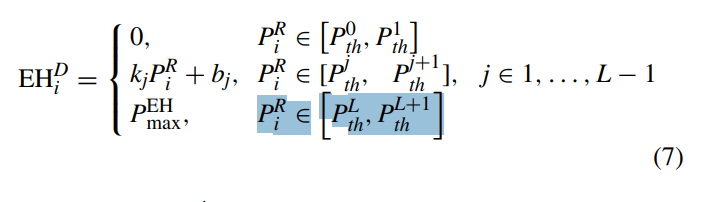

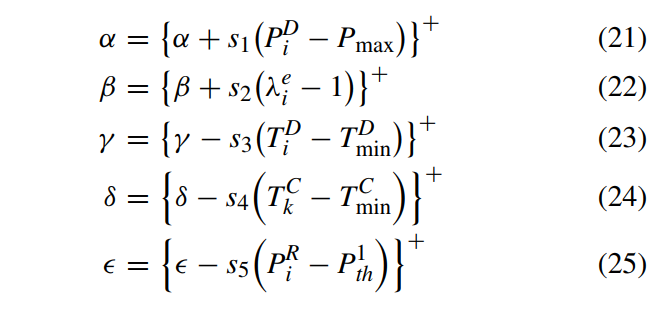

## Preference lists for Constraint Stable Matching Algorithm 

In this section, a perference will be constructed based on the result from the Outer loop Algorithm. From the outer loop Algorithm , we should get three different array for storing the data: **Transmission power, power splitting ratio and Energy efficiency. **And through the Algorithm 2, for each segment of links i in SWIPT-Enabled D2D systems we should get certain optimal values of three parameters mentioned above at a certain segment of piecewise EH model j.

And for this section, we should create two preference lists for** SWIPT-Enabled sets** and **CUE** sets

- For **SWIPT-Enabled links** , we defintely want them to match  thoses links in **CUE set **which can maximize its Energy efficiency for each segment since want the sum of each segment's Energy efficiency to be **maximum.**

               1.To achieve that, we first need to sort the link in CUE set,remember from algorithm 2, we already get a optimal EE array for each segment i where each segment's Energy efficiecny is already reaches the maximum point, now what we have to do is find the corresponding segment k in SiD which can help the D2D link to get the corresponding maximum value

               2.So, we first need to traverse the Energy Efficiecny array, sort them in the descend order, and for each segment, we have a corresponding i segment i which is easy to find in the D2D link set, so what we need to do is to find corresponding k.

              3. To solve that, we need to first traverse the CUE set then test each segment k to check if the current segment k of CUE is apporiate for help the segment i of SWIPT-Enabled D2D link to achieve the maximum value of EE of its segment.And all of this can be solved using the equation below:

We just need to use the function for each loop and store them into a temporary value

          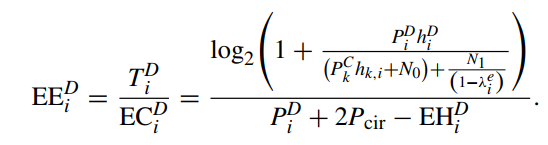 

       2. And for the CUE, the partner selection can also be done by using the same methodology: at the CUE link set, for each interation, we need to scan the D2D link, and sort the interference power in ascending order and place the corresponding D2D link, then the preference list for CUE can be established.

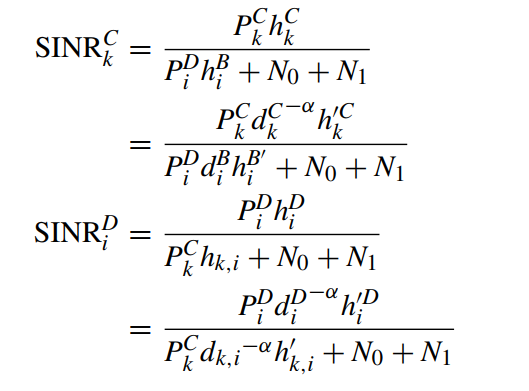

where the interference powe can be calculated by P_iD*d_iB*h_iB_rayleigh. Where the h_iB_rayleigh is the rayleigh channel coefficient and diB is the distance from D2D link to basestation. **Since the method for calculating rayleigh channel coefficient haven't been figured out, so hB_rayleigh will be just used for it temporarily.**

- First traverse the CUE set, then for eack link in the CUE set k, scan each link i in SWIPT-Enabled group.

- For each link i, there will be intereference between i and basestation, create an array for storing the interference power on single D2D link

- For each loop of D2D link, sort sort each the intereference power in ascending oder

- Then repeat the step 1 and step 2, placing the corresponding D2D link in the partner selection set using hashmap. 

- In this case, for each link k from CUE set, the interference power will not get affected by link k.                            

function[partner_CUE,partner_D2D]=preference(EE,PD,lambda,SiD,EhaD)
syms pkc hD h_interference Pir PR hB_rayleigh dB
for i=1:size(EhaD,2)
    %for each D2D link paired with CUE k, there will be a corresponding EE,
    %Before pushing the link into the map, first sort the EE sub array in
    %descending order, then push the corresponding link
    EE_temp=sort(EE(i,:),'descend');
    for p=1:size(EE_temp,2)
        find=false;
        for k=1:size(SiD,2)
            Throughput_temp=Throughput_D(lambda(i),PD(i),pkc,h_interference(i,k),hD(i));
            EH_temp=Eenergy_harvesting(PR(i));
            EC_temp=Energy_Consumption(PD(i),Pir,EH_temp);
            EE_cal=Throughput_temp/EC_temp;
            if EE_cal==EE_temp(p)
                partner_D2D(i,p)=SiD(k);
                find=true;
            end
            if find==true
                break;
            end
        end
        %This means that, for a certain value of EE for D2D link i,there is
        %no such a CUE which can make the link i achieve that.
        if find==false
            partner_D2D(i,p)=0;
        end
        
    end
end


M = containers.Map('KeyType','double','ValueType','int32');
%first 
for k=1:size(SiD,2)
    for i=size(EhaD,2)
        h_interference(i)=dB(i)*PD(i)*hB_rayleigh(i);
        M=containers.Map(h_interference(i), EhaD(i));
    end
    %for each k, sort the interference vector in ascending order.
    h_interference(k,:)=sort(h_interference(k,:));
end
for k=1:size(SiD,2)
    for i=size(EhaD,2)
        link=M(h_interference(i));
        partner_CUE(k,i)=link;
    end
end
end

## **One to one Constraint Stabel Matching Algorithm**

So if all the SWIPT links can find their partners, the matching will be perferct. However, sometimes due to bad channel condition or long Distance form D2D link, to meet the Throughput put as shwon in the preference link code, Some D2D link(i for each iteration) can only select limited number of CUE links to meet the requirement. Also for CUE sets, if the D2D link i already chooses some links from the CUE set, but when you input the selected CUE link and put it into the CUE partner selection set, the CUE will not choose them, then the D2D link will be unmatched

So, an one to one constraint Stable Matching Algorithm will be introuduced to solve this question to make each D2D link match with an approiate CUE.

First, we will let the SWIPT-Enabled D2D link propose to the most preferred CUE link, and by most preferred, we mean when the current D2D link i choose this CUE k, it can achieve the maximum value of EE on this link, and since it it already sort the CUE in descending order ,so for each D2D link i's partner selection, the first one CUE should always be the one which can help the D2D link i achieve the maximum value of EE.

As mentioned in the preference list before, for each D2D link, it should have a corresponding preference list ,like [2 6 1 7 0 0 4 5], which means that the CUE 2 which can help the link 1 to get the first EE from EE array, and as we already sort the EE in descending order, then we can automatically say the CUE 2 is D2D link i most preferred partner. If the first element is 0 which means that the there is no such a CUE which can help the current D2D link i achieve the maximum value, so we will search for the partner to find the first none-zero link which will make D2D achive the maximum vlaue from EE array.

Then we need to check if the most preferred are called from only one D2D link or more, for example, here is a partner selection set:

     2     6     1     7     3     8     4     5

     2    4    3     7     8    5      1       6

     7    4    3     1     5    8     2       1

 It is obvious that, for **most preferred CUE, there are D2D link 1 and D2D link 2 calling it.**

function [matched, unmatched]=matching(EhaD,SiD,partner_D,partner_C)
matched={};
while isempty(EhaD)==0
    for i=size(EhaD,2)
        %check the current link's most preferred CUE
        %find the first element that is not zero which means that the found
        %CUE is the most preferred CUE fort the current D2D link.
        most_preferred=partner_D(i,1);
        %Extracat the whole column for the most preferred from partner D
        most_preferrend_column=partner_D(:,1);
        temp=most_preferrend_column(most_preferrend_column==most_preferred); 
        if size(temp,1)==1
            matched{i}=[i,most_preferred];
            EhaD(i)=[];
        %current chosen CUE k received a proposal from not only one D2D
        %link, so check all of the D2D links proposing to same CUE.
        elseif size(temp,1)>1
            proposing_D2D=find(most_preferrend_column==most_preferred);
            
        end
    
    end
end
end
